# Avoid Obstacles Using Reinforcement Learning for Mobile Robots

This example uses Deep Deterministic Policy Gradient (DDPG) based reinforcement learning to develop a strategy for a mobile robot to avoid obstacles. For a brief summary of the DDPG algorithm, see [Deep Deterministic Policy Gradient Agents](docid:rl_ug#mw_66c8fe60-f58e-4bdb-904a-21d442f0a879). 

This example scenario trains a mobile robot to avoid obstacles given range sensor readings that detect obstacles in the map. The objective of the reinforcement learning algorithm is to learn what controls (linear and angular velocity), the robot should use to avoid colliding into obstacles. This example uses an occupancy map of a known environment to generate range sensor readings, detect obstacles, and check collisions the robot may make. The range sensor readings are the observations for the DDPG agent, and the linear and angular velocity controls are the action.

### Load Map

Load a map matrix, `simpleMap`, that represents the environment for the robot.

load Environment1 BW
%load Environment2 BW
%load Environment3 BW

mapMatrix = BW;
mapScale = 1;

### Range Sensor Parameters

Next, set up a `rangeSensor` object which simulates a noisy range sensor. The range sensor readings are considered observations by the agent. Define the angular positions of the range readings, the max range, and the noise parameters.

scanAngles = -3*pi/8:pi/12:3*pi/8; %angulos lidar
maxRange = 70;%range
lidarNoiseVariance = 0.1^2;
lidarNoiseSeeds = randi(intmax,size(scanAngles));

### Robot Parameters

The action of the agent is a two-dimensional vector $a = [v , \omega] $ where $v$ and $\omega$ are the linear and angular velocities of our robot. The DDPG agent uses normalized inputs for both the angular and linear velocities, meaning the actions of the agent are a scalar between -1 and 1, which is multiplied by the `maxLinSpeed` and `maxAngSpeed` parameters to get the actual control. Specify this maximum linear and angular velocity.

Also, specify the initial position of the robot as `[x y theta]`.

% Max speed parameters
maxLinSpeed = 0.9; %lineal speed
maxAngSpeed = 0.9; %angular speed

%%%%route1envieronment1%%%%%
initX = 34; %start point x
initY = 31; %start point y
%%%%%%%%%%%%%%
initTheta = pi/2;%ang init

### Show Map and Robot Positions

To visualize the actions of the robot, create a figure. Start by showing the occupancy map and plot the initial position of the robot.

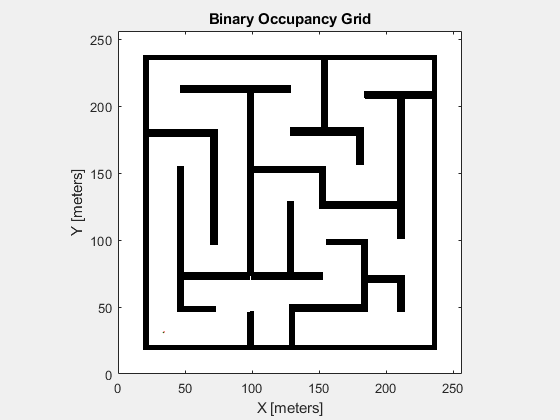

fig = figure("Name","BW");
set(fig, "Visible","on");
ax = axes(fig);

show(binaryOccupancyMap(mapMatrix),"Parent",ax);
hold on
plotTransforms([initX,initY,0],eul2quat([initTheta,0,0]),"MeshFilePath","groundvehicle.stl","View","2D");
light;
hold off

### Environment Interface

Create an environment model that takes the action, and gives the observation and reward signals. Specify the provided example model name, ex`ampleHelperAvoidObstaclesMobileRobot`, the simulation time parameters, and the agent block name.

mdl = "exampleHelperAvoidObstaclesMobileRobot";
Tfinal = 1000;
sampleTime = 0.1;

agentBlk = mdl + "/Agent";

Open the model.

open_system(mdl)

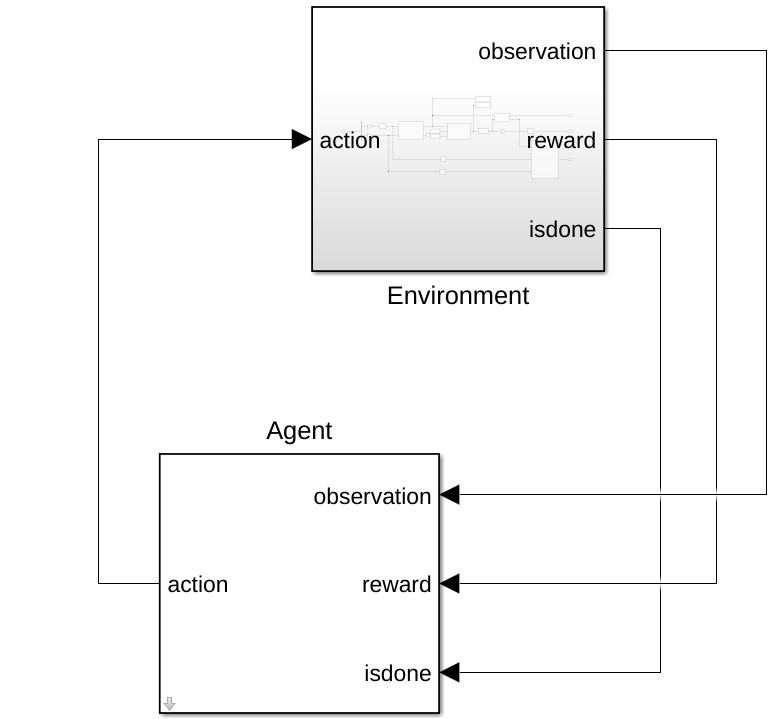

The model contains the `Environment` and `Agent` blocks. The `Agent` block is not defined yet.

Inside the `Environment` Subsystem block, you should see a model for simulating the robot and sensor data. The subsystem takes in the action, generates the observation signal based on the range sensor readings, and calculates the reward based on the distance from obstacles, and the effort of the action commands.

open_system(mdl + "/Environment")

Define observation parameters, `obsInfo`, using the `rlNumericSpec` object and giving the lower and upper limit for the range readings with enough elements for each angular position in the range sensor.

obsInfo = rlNumericSpec([numel(scanAngles) 1],...
    "LowerLimit",zeros(numel(scanAngles),1),...
    "UpperLimit",ones(numel(scanAngles),1)*maxRange);
numObservations = obsInfo.Dimension(1);

Define action parameters, `actInfo`. The action is the control command vector, $a = [v , \omega] $, normalized to $[-1, 1]$.

numActions = 2;
actInfo = rlNumericSpec([numActions 1],...
    "LowerLimit",-1,...
    "UpperLimit",1);

Build the environment interface object using [`rlSimulinkEnv`](docid:rl_ref.mw_12cc40dc-3191-4a23-af71-1625696c1a14). Specify the model, agent block name, observation parameters, and action parameters. Set the reset function for the simulation using `exampleHelperRLAvoidObstaclesResetFcn`. This function restarts the simulation by placing the robot in a new random location to begin avoiding obstacles. 

env = rlSimulinkEnv(mdl,agentBlk,obsInfo,actInfo);
env.ResetFcn = @(in)exampleHelperRLAvoidObstaclesResetFcn(in,scanAngles,maxRange,mapMatrix);
env.UseFastRestart = "On";

For another example that sets up a Simulink® environment for training, see [Create Simulink Environment and Train Agent](docid:rl_ug.mw_873bd3fc-b713-4e71-b776-9758762d592c).

## DDPG Agent

A DDPG agent approximates the long-term reward given observations and actions using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the observation and action, and one output. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

statePath = [
    featureInputLayer(numObservations, "Normalization","none","Name","State")
    fullyConnectedLayer(50,"Name","CriticStateFC1")
    reluLayer("Name","CriticRelu1")
    fullyConnectedLayer(25,"Name","CriticStateFC2")];
actionPath = [
    featureInputLayer(numActions,"Normalization","none","Name","Action")
    fullyConnectedLayer(25,"Name","CriticActionFC1")];
commonPath = [
    additionLayer(2,"Name","add")
    reluLayer("Name","CriticCommonRelu")
    fullyConnectedLayer(1,"Name","CriticOutput")];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,"CriticStateFC2","add/in1");
criticNetwork = connectLayers(criticNetwork,"CriticActionFC1","add/in2");
criticNetwork = dlnetwork(criticNetwork);

Next, specify options for the critic optimizer using `rlOptimizerOptions`.

Finally, create the critic representation using the specified deep neural network and options. You must also specify the action and observation specifications for the critic, which you obtain from the environment interface. For more information, see [rlQValueFunction](docid:rl_ref#mw_e6e7abac-0a33-423b-8473-1409879db701).

criticOptions = rlOptimizerOptions("LearnRate",1e-3,"L2RegularizationFactor",1e-4,"GradientThreshold",1);
critic = rlQValueFunction(criticNetwork,obsInfo,actInfo,"ObservationInputNames","State","ActionInputNames","Action");

A DDPG agent decides which action to take given observations using an actor representation. To create the actor, first create a deep neural network with one input, the observation, and one output, the action.

Finally, construct the actor in a similar manner as the critic. For more information, see [`rlContinuousDeterministicActor`](docid:rl_ref#mw_c2909424-90f4-4a52-803b-73310483e6c3).

actorNetwork = [
    featureInputLayer(numObservations,"Normalization","none","Name","State")
    fullyConnectedLayer(50,"Name","actorFC1")
    reluLayer("Name","actorReLU1")
    fullyConnectedLayer(50, "Name","actorFC2")
    reluLayer("Name","actorReLU2")
    fullyConnectedLayer(2, "Name","actorFC3")
    tanhLayer("Name","Action")];
actorNetwork = dlnetwork(actorNetwork);

actorOptions = rlOptimizerOptions("LearnRate",1e-4,"L2RegularizationFactor",1e-4,"GradientThreshold",1);
actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

### Create DDPG agent object

Specify the agent options.

agentOpts = rlDDPGAgentOptions(...
    "SampleTime",sampleTime,...
    "ActorOptimizerOptions",actorOptions,...
    "CriticOptimizerOptions",criticOptions,...
    "DiscountFactor",0.995, ...
    "MiniBatchSize",128, ...
    "ExperienceBufferLength",1e6); 

agentOpts.NoiseOptions.Variance = 0.1;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;

Create the `rlDDPGAgent` object. The `obstacleAvoidanceAgent` variable is used in the model for the `Agent` block.

obstacleAvoidanceAgent = rlDDPGAgent(actor,critic,agentOpts);
open_system(mdl + "/Agent")

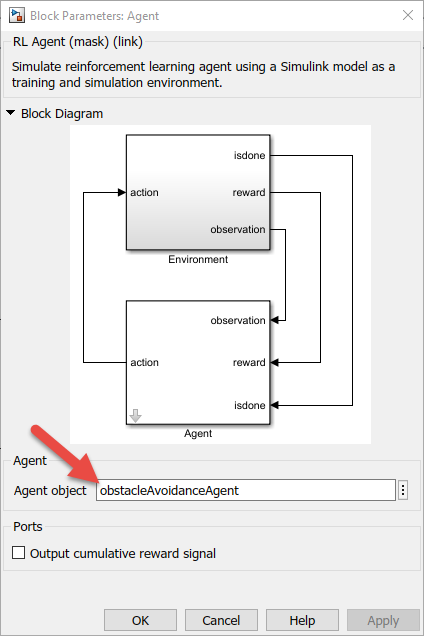

## Reward

The reward function for the agent is modeled as shown.

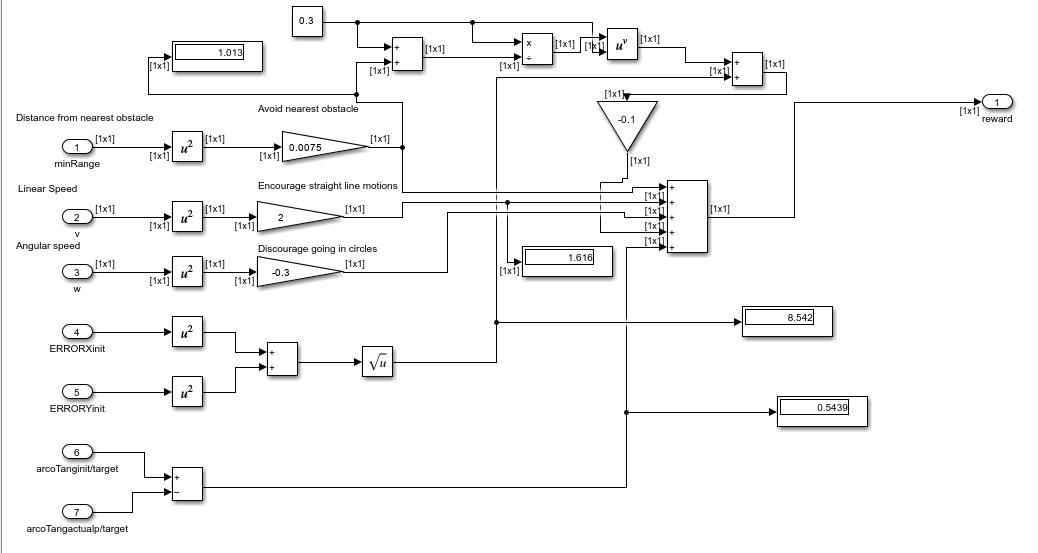

The agent is rewarded to avoid the nearest obstacle, which minimizes the worst-case scenario. Additionally, the agent is given a positive reward for higher linear speeds, and is given a negative reward for higher angular speeds. This rewarding strategy discourages the agent's behavior of going in circles. Tuning your rewards is key to properly training an agent, so your rewards vary depending on your application.

% porfavor, aqui haz que estas variables de target vayan a simulink con un
% bloque de from workspace
targetX = 221;
targetY = 220;

## Train Agent

maxEpisodes = 1000;

maxSteps = ceil(Tfinal/sampleTime);
trainOpts = rlTrainingOptions(...
    "MaxEpisodes",maxEpisodes, ...
    "MaxStepsPerEpisode",maxSteps, ...
    "ScoreAveragingWindowLength",50, ...
    "StopTrainingCriteria","AverageReward", ...
    "StopTrainingValue",9999, ...
    "Verbose", true, ...
    "Plots","training-progress");

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally-intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true; % Toggle this to true for training. 

if doTraining
    % Train the agent.
    trainingStats = train(obstacleAvoidanceAgent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load exampleHelperAvoidObstaclesAgent obstacleAvoidanceAgent
end

Episode:   1/1000 | Episode reward: -49251.55 | Episode steps: 1905 | Average reward: -49251.55 | Step Count: 1905 | Episode Q0:     0.00


Episode:   2/1000 | Episode reward: -10716.83 | Episode steps:  404 | Average reward: -29984.19 | Step Count: 2309 | Episode Q0:    -0.11


Episode:   3/1000 | Episode reward: -13835.85 | Episode steps:  531 | Average reward: -24601.41 | Step Count: 2840 | Episode Q0:    -0.28


Episode:   4/1000 | Episode reward: -26237.04 | Episode steps: 1013 | Average reward: -25010.32 | Step Count: 3853 | Episode Q0:    -0.52


Episode:   5/1000 | Episode reward: -38108.83 | Episode steps: 1459 | Average reward: -27630.02 | Step Count: 5312 | Episode Q0:    -0.89


Episode:   6/1000 | Episode reward: -14310.42 | Episode steps:  531 | Average reward: -25410.09 | Step Count: 5843 | Episode Q0:    -1.51


Episode:   7/1000 | Episode reward: -33309.84 | Episode steps: 1323 | Average reward: -26538.62 | Step Count: 7166 | Episode Q0:    -2.33


Episode:   8/1000 | Episode reward: -11189.56 | Episode steps:  415 | Average reward: -24619.99 | Step Count: 7581 | Episode Q0:    -3.49


Episode:   9/1000 | Episode reward: -54942.88 | Episode steps: 2162 | Average reward: -27989.20 | Step Count: 9743 | Episode Q0:    -4.93


Episode:  10/1000 | Episode reward: -14378.62 | Episode steps:  555 | Average reward: -26628.14 | Step Count: 10298 | Episode Q0:    -7.09


Episode:  11/1000 | Episode reward: -12974.61 | Episode steps:  497 | Average reward: -25386.91 | Step Count: 10795 | Episode Q0:    -9.71


Episode:  12/1000 | Episode reward: -53955.65 | Episode steps: 2099 | Average reward: -27767.64 | Step Count: 12894 | Episode Q0:   -12.85


Episode:  13/1000 | Episode reward: -104582.93 | Episode steps: 4101 | Average reward: -33676.51 | Step Count: 16995 | Episode Q0:   -17.20


Episode:  14/1000 | Episode reward: -9649.80 | Episode steps:  356 | Average reward: -31960.31 | Step Count: 17351 | Episode Q0:   -22.31


Episode:  15/1000 | Episode reward: -58799.09 | Episode steps: 2392 | Average reward: -33749.57 | Step Count: 19743 | Episode Q0:   -28.09


Episode:  16/1000 | Episode reward: -144055.89 | Episode steps: 5684 | Average reward: -40643.71 | Step Count: 25427 | Episode Q0:   -31.08


Episode:  17/1000 | Episode reward: -44467.23 | Episode steps: 1691 | Average reward: -40868.62 | Step Count: 27118 | Episode Q0:   -32.71


Episode:  18/1000 | Episode reward: -12737.43 | Episode steps:  487 | Average reward: -39305.78 | Step Count: 27605 | Episode Q0:   -34.48


Episode:  19/1000 | Episode reward: -46099.21 | Episode steps: 1717 | Average reward: -39663.33 | Step Count: 29322 | Episode Q0:   -36.32


Episode:  20/1000 | Episode reward: -76483.19 | Episode steps: 3044 | Average reward: -41504.32 | Step Count: 32366 | Episode Q0:   -38.18


Episode:  21/1000 | Episode reward: -120201.28 | Episode steps: 4619 | Average reward: -45251.80 | Step Count: 36985 | Episode Q0:   -40.05


Episode:  22/1000 | Episode reward: -37808.33 | Episode steps: 1501 | Average reward: -44913.46 | Step Count: 38486 | Episode Q0:   -42.03


Episode:  23/1000 | Episode reward: -112271.64 | Episode steps: 4394 | Average reward: -47842.07 | Step Count: 42880 | Episode Q0:   -44.05


Episode:  24/1000 | Episode reward: -20297.31 | Episode steps:  753 | Average reward: -46694.37 | Step Count: 43633 | Episode Q0:   -46.09


Episode:  25/1000 | Episode reward: -249632.66 | Episode steps: 10000 | Average reward: -54811.91 | Step Count: 53633 | Episode Q0:   -48.14


Episode:  26/1000 | Episode reward: -80969.11 | Episode steps: 3036 | Average reward: -55817.95 | Step Count: 56669 | Episode Q0:   -49.85


Episode:  27/1000 | Episode reward: -187893.92 | Episode steps: 7045 | Average reward: -60709.65 | Step Count: 63714 | Episode Q0:   -52.19


Episode:  28/1000 | Episode reward: -47833.85 | Episode steps: 1786 | Average reward: -60249.80 | Step Count: 65500 | Episode Q0:   -54.47


Episode:  29/1000 | Episode reward: -10738.47 | Episode steps:  405 | Average reward: -58542.52 | Step Count: 65905 | Episode Q0:   -56.64


Episode:  30/1000 | Episode reward: -9730.05 | Episode steps:  367 | Average reward: -56915.44 | Step Count: 66272 | Episode Q0:   -58.80


Episode:  31/1000 | Episode reward: -101906.37 | Episode steps: 3841 | Average reward: -58366.76 | Step Count: 70113 | Episode Q0:   -60.91


Episode:  32/1000 | Episode reward: -38238.32 | Episode steps: 1419 | Average reward: -57737.74 | Step Count: 71532 | Episode Q0:   -63.14


Episode:  33/1000 | Episode reward: -206658.22 | Episode steps: 8015 | Average reward: -62250.48 | Step Count: 79547 | Episode Q0:   -65.58


Episode:  34/1000 | Episode reward: -30628.01 | Episode steps: 1133 | Average reward: -61320.41 | Step Count: 80680 | Episode Q0:   -67.80


Episode:  35/1000 | Episode reward: -11404.48 | Episode steps:  422 | Average reward: -59894.24 | Step Count: 81102 | Episode Q0:   -69.91


Episode:  36/1000 | Episode reward: -107702.62 | Episode steps: 4131 | Average reward: -61222.25 | Step Count: 85233 | Episode Q0:   -72.25


Episode:  37/1000 | Episode reward: -64297.53 | Episode steps: 2419 | Average reward: -61305.37 | Step Count: 87652 | Episode Q0:   -74.58


Episode:  38/1000 | Episode reward: -34271.43 | Episode steps: 1303 | Average reward: -60593.95 | Step Count: 88955 | Episode Q0:   -76.83


Episode:  39/1000 | Episode reward: -35628.58 | Episode steps: 1316 | Average reward: -59953.81 | Step Count: 90271 | Episode Q0:   -79.14


Episode:  40/1000 | Episode reward: -54397.90 | Episode steps: 2015 | Average reward: -59814.91 | Step Count: 92286 | Episode Q0:   -81.44


Episode:  41/1000 | Episode reward: -8105.80 | Episode steps:  304 | Average reward: -58553.71 | Step Count: 92590 | Episode Q0:   -83.74


Episode:  42/1000 | Episode reward: -21491.01 | Episode steps:  795 | Average reward: -57671.27 | Step Count: 93385 | Episode Q0:   -86.23


Episode:  43/1000 | Episode reward: -18159.77 | Episode steps:  671 | Average reward: -56752.40 | Step Count: 94056 | Episode Q0:   -88.46


Episode:  44/1000 | Episode reward: -11460.81 | Episode steps:  435 | Average reward: -55723.04 | Step Count: 94491 | Episode Q0:   -90.81


Episode:  45/1000 | Episode reward: -9888.88 | Episode steps:  374 | Average reward: -54704.51 | Step Count: 94865 | Episode Q0:   -93.15


Episode:  46/1000 | Episode reward: -7932.35 | Episode steps:  297 | Average reward: -53687.72 | Step Count: 95162 | Episode Q0:   -95.56


Episode:  47/1000 | Episode reward: -16775.30 | Episode steps:  621 | Average reward: -52902.35 | Step Count: 95783 | Episode Q0:   -97.90


Episode:  48/1000 | Episode reward: -37330.37 | Episode steps: 1435 | Average reward: -52577.93 | Step Count: 97218 | Episode Q0:  -100.15


Episode:  49/1000 | Episode reward: -8536.63 | Episode steps:  321 | Average reward: -51679.13 | Step Count: 97539 | Episode Q0:  -102.75


Episode:  50/1000 | Episode reward: -8061.46 | Episode steps:  304 | Average reward: -50806.78 | Step Count: 97843 | Episode Q0:  -104.98


Episode:  51/1000 | Episode reward: -9708.43 | Episode steps:  366 | Average reward: -50015.92 | Step Count: 98209 | Episode Q0:  -107.28


Episode:  52/1000 | Episode reward: -8128.17 | Episode steps:  304 | Average reward: -49964.14 | Step Count: 98513 | Episode Q0:  -109.72


Episode:  53/1000 | Episode reward: -11423.90 | Episode steps:  436 | Average reward: -49915.90 | Step Count: 98949 | Episode Q0:  -112.10


Episode:  54/1000 | Episode reward: -9010.62 | Episode steps:  340 | Average reward: -49571.37 | Step Count: 99289 | Episode Q0:  -114.40


Episode:  55/1000 | Episode reward: -16273.00 | Episode steps:  643 | Average reward: -49134.66 | Step Count: 99932 | Episode Q0:  -116.89


Episode:  56/1000 | Episode reward: -60632.71 | Episode steps: 2388 | Average reward: -50061.10 | Step Count: 102320 | Episode Q0:  -119.20


Episode:  57/1000 | Episode reward: -33388.77 | Episode steps: 1318 | Average reward: -50062.68 | Step Count: 103638 | Episode Q0:  -121.64


Episode:  58/1000 | Episode reward: -12728.30 | Episode steps:  488 | Average reward: -50093.46 | Step Count: 104126 | Episode Q0:  -123.88


Episode:  59/1000 | Episode reward: -35351.76 | Episode steps: 1426 | Average reward: -49701.63 | Step Count: 105552 | Episode Q0:  -126.39


Episode:  60/1000 | Episode reward: -15880.11 | Episode steps:  616 | Average reward: -49731.66 | Step Count: 106168 | Episode Q0:  -128.75


Episode:  61/1000 | Episode reward: -19974.00 | Episode steps:  774 | Average reward: -49871.65 | Step Count: 106942 | Episode Q0:  -130.94


Episode:  62/1000 | Episode reward: -28976.90 | Episode steps: 1127 | Average reward: -49372.08 | Step Count: 108069 | Episode Q0:  -133.21


Episode:  63/1000 | Episode reward: -129364.10 | Episode steps: 5136 | Average reward: -49867.70 | Step Count: 113205 | Episode Q0:  -135.72


Episode:  64/1000 | Episode reward: -10797.78 | Episode steps:  408 | Average reward: -49890.66 | Step Count: 113613 | Episode Q0:  -138.05


Episode:  65/1000 | Episode reward: -185263.19 | Episode steps: 7095 | Average reward: -52419.94 | Step Count: 120708 | Episode Q0:  -140.25


Episode:  66/1000 | Episode reward: -134079.28 | Episode steps: 5121 | Average reward: -52220.41 | Step Count: 125829 | Episode Q0:  -142.88


Episode:  67/1000 | Episode reward: -168367.89 | Episode steps: 6433 | Average reward: -54698.42 | Step Count: 132262 | Episode Q0:  -145.28


Episode:  68/1000 | Episode reward: -57461.74 | Episode steps: 2218 | Average reward: -55592.91 | Step Count: 134480 | Episode Q0:  -147.79


Episode:  69/1000 | Episode reward: -70324.15 | Episode steps: 2655 | Average reward: -56077.41 | Step Count: 137135 | Episode Q0:  -150.11


Episode:  70/1000 | Episode reward: -125179.73 | Episode steps: 4885 | Average reward: -57051.34 | Step Count: 142020 | Episode Q0:  -152.61


Episode:  71/1000 | Episode reward: -104766.57 | Episode steps: 3981 | Average reward: -56742.65 | Step Count: 146001 | Episode Q0:  -154.95


Episode:  72/1000 | Episode reward: -260077.43 | Episode steps: 10000 | Average reward: -61188.03 | Step Count: 156001 | Episode Q0:  -157.42


Episode:  73/1000 | Episode reward: -218501.17 | Episode steps: 8273 | Average reward: -63312.62 | Step Count: 164274 | Episode Q0:  -159.71


Episode:  74/1000 | Episode reward: -261885.93 | Episode steps: 10000 | Average reward: -68144.39 | Step Count: 174274 | Episode Q0:  -162.29


Episode:  75/1000 | Episode reward: -258579.71 | Episode steps: 10000 | Average reward: -68323.33 | Step Count: 184274 | Episode Q0:  -164.73


Episode:  76/1000 | Episode reward: -262790.01 | Episode steps: 10000 | Average reward: -71959.75 | Step Count: 194274 | Episode Q0:  -167.00


Episode:  77/1000 | Episode reward: -265020.74 | Episode steps: 10000 | Average reward: -73502.29 | Step Count: 204274 | Episode Q0:  -169.49


Episode:  78/1000 | Episode reward: -263257.82 | Episode steps: 10000 | Average reward: -77810.77 | Step Count: 214274 | Episode Q0:  -172.02


Episode:  79/1000 | Episode reward: -263151.91 | Episode steps: 10000 | Average reward: -82859.03 | Step Count: 224274 | Episode Q0:  -174.43


Episode:  80/1000 | Episode reward: -262641.04 | Episode steps: 10000 | Average reward: -87917.25 | Step Count: 234274 | Episode Q0:  -176.70


Episode:  81/1000 | Episode reward: -265092.12 | Episode steps: 10000 | Average reward: -91180.97 | Step Count: 244274 | Episode Q0:  -179.34


Episode:  82/1000 | Episode reward: -261329.61 | Episode steps: 10000 | Average reward: -95642.80 | Step Count: 254274 | Episode Q0:  -181.70


Episode:  83/1000 | Episode reward: -259423.71 | Episode steps: 10000 | Average reward: -96698.10 | Step Count: 264274 | Episode Q0:  -184.18


Episode:  84/1000 | Episode reward: -51251.76 | Episode steps: 1948 | Average reward: -97110.58 | Step Count: 266222 | Episode Q0:  -186.49


Episode:  85/1000 | Episode reward: -39487.09 | Episode steps: 1519 | Average reward: -97672.23 | Step Count: 267741 | Episode Q0:  -189.02


Episode:  86/1000 | Episode reward: -254566.89 | Episode steps: 10000 | Average reward: -100609.52 | Step Count: 277741 | Episode Q0:  -191.38


Episode:  87/1000 | Episode reward: -40510.08 | Episode steps: 1568 | Average reward: -100133.77 | Step Count: 279309 | Episode Q0:  -193.77


Episode:  88/1000 | Episode reward: -9391.73 | Episode steps:  365 | Average reward: -99636.17 | Step Count: 279674 | Episode Q0:  -196.20


Episode:  89/1000 | Episode reward: -10287.49 | Episode steps:  401 | Average reward: -99129.35 | Step Count: 280075 | Episode Q0:  -198.62


Episode:  90/1000 | Episode reward: -18344.87 | Episode steps:  731 | Average reward: -98408.29 | Step Count: 280806 | Episode Q0:  -200.99


Episode:  91/1000 | Episode reward: -28587.79 | Episode steps: 1171 | Average reward: -98817.93 | Step Count: 281977 | Episode Q0:  -203.36


Episode:  92/1000 | Episode reward: -23331.01 | Episode steps:  929 | Average reward: -98854.73 | Step Count: 282906 | Episode Q0:  -205.46


Episode:  93/1000 | Episode reward: -10394.30 | Episode steps:  398 | Average reward: -98699.42 | Step Count: 283304 | Episode Q0:  -207.98


Episode:  94/1000 | Episode reward: -11068.56 | Episode steps:  425 | Average reward: -98691.58 | Step Count: 283729 | Episode Q0:  -210.38


Episode:  95/1000 | Episode reward: -8492.04 | Episode steps:  323 | Average reward: -98663.64 | Step Count: 284052 | Episode Q0:  -212.57


Episode:  96/1000 | Episode reward: -8944.39 | Episode steps:  341 | Average reward: -98683.88 | Step Count: 284393 | Episode Q0:  -215.04


Episode:  97/1000 | Episode reward: -8003.67 | Episode steps:  304 | Average reward: -98508.45 | Step Count: 284697 | Episode Q0:  -217.39


Episode:  98/1000 | Episode reward: -6752.18 | Episode steps:  255 | Average reward: -97896.89 | Step Count: 284952 | Episode Q0:  -220.06


Episode:  99/1000 | Episode reward: -6704.74 | Episode steps:  253 | Average reward: -97860.25 | Step Count: 285205 | Episode Q0:  -222.16


Episode: 100/1000 | Episode reward: -6548.77 | Episode steps:  247 | Average reward: -97829.99 | Step Count: 285452 | Episode Q0:  -224.44


Episode: 101/1000 | Episode reward: -6618.13 | Episode steps:  249 | Average reward: -97768.19 | Step Count: 285701 | Episode Q0:  -227.01


Episode: 102/1000 | Episode reward: -6579.42 | Episode steps:  247 | Average reward: -97737.21 | Step Count: 285948 | Episode Q0:  -229.23


Episode: 103/1000 | Episode reward: -36531.48 | Episode steps: 1358 | Average reward: -98239.36 | Step Count: 287306 | Episode Q0:  -231.55


Episode: 104/1000 | Episode reward: -261673.50 | Episode steps: 9726 | Average reward: -103292.62 | Step Count: 297032 | Episode Q0:  -234.10


Episode: 105/1000 | Episode reward: -266426.72 | Episode steps: 10000 | Average reward: -108295.70 | Step Count: 307032 | Episode Q0:  -237.01


Episode: 106/1000 | Episode reward: -32144.49 | Episode steps: 1197 | Average reward: -107725.93 | Step Count: 308229 | Episode Q0:  -239.68


Episode: 107/1000 | Episode reward: -267527.04 | Episode steps: 10000 | Average reward: -112408.70 | Step Count: 318229 | Episode Q0:  -242.06


Episode: 108/1000 | Episode reward: -268401.63 | Episode steps: 10000 | Average reward: -117522.16 | Step Count: 328229 | Episode Q0:  -244.60


Episode: 109/1000 | Episode reward: -269670.82 | Episode steps: 10000 | Average reward: -122208.55 | Step Count: 338229 | Episode Q0:  -247.13


Episode: 110/1000 | Episode reward: -36142.18 | Episode steps: 1345 | Average reward: -122613.79 | Step Count: 339574 | Episode Q0:  -249.56


Episode: 111/1000 | Episode reward: -7307.88 | Episode steps:  274 | Average reward: -122360.46 | Step Count: 339848 | Episode Q0:  -252.16


Episode: 112/1000 | Episode reward: -6944.78 | Episode steps:  261 | Average reward: -121919.82 | Step Count: 340109 | Episode Q0:  -254.46


Episode: 113/1000 | Episode reward: -6824.49 | Episode steps:  257 | Average reward: -119469.03 | Step Count: 340366 | Episode Q0:  -257.01


Episode: 114/1000 | Episode reward: -6960.33 | Episode steps:  262 | Average reward: -119392.28 | Step Count: 340628 | Episode Q0:  -259.40


Episode: 115/1000 | Episode reward: -6996.74 | Episode steps:  264 | Average reward: -115826.95 | Step Count: 340892 | Episode Q0:  -261.78


Episode: 116/1000 | Episode reward: -7101.81 | Episode steps:  268 | Average reward: -113287.40 | Step Count: 341160 | Episode Q0:  -264.21


Episode: 117/1000 | Episode reward: -7203.99 | Episode steps:  272 | Average reward: -110064.12 | Step Count: 341432 | Episode Q0:  -266.72


Episode: 118/1000 | Episode reward: -7689.42 | Episode steps:  291 | Average reward: -109068.68 | Step Count: 341723 | Episode Q0:  -269.05


Episode: 119/1000 | Episode reward: -7918.47 | Episode steps:  300 | Average reward: -107820.56 | Step Count: 342023 | Episode Q0:  -271.54


Episode: 120/1000 | Episode reward: -8759.58 | Episode steps:  333 | Average reward: -105492.16 | Step Count: 342356 | Episode Q0:  -273.95


Episode: 121/1000 | Episode reward: -9349.14 | Episode steps:  356 | Average reward: -103583.81 | Step Count: 342712 | Episode Q0:  -276.51


Episode: 122/1000 | Episode reward: -9939.40 | Episode steps:  379 | Average reward: -98581.05 | Step Count: 343091 | Episode Q0:  -278.80


Episode: 123/1000 | Episode reward: -12430.49 | Episode steps:  478 | Average reward: -94459.64 | Step Count: 343569 | Episode Q0:  -281.23


Episode: 124/1000 | Episode reward: -11814.22 | Episode steps:  453 | Average reward: -89458.20 | Step Count: 344022 | Episode Q0:  -283.54


Episode: 125/1000 | Episode reward: -15076.15 | Episode steps:  584 | Average reward: -84588.13 | Step Count: 344606 | Episode Q0:  -285.98


Episode: 126/1000 | Episode reward: -63776.39 | Episode steps: 2910 | Average reward: -80607.86 | Step Count: 347516 | Episode Q0:  -288.35


Episode: 127/1000 | Episode reward: -38209.69 | Episode steps: 1610 | Average reward: -76071.64 | Step Count: 349126 | Episode Q0:  -290.75


Episode: 128/1000 | Episode reward: -14896.27 | Episode steps:  588 | Average reward: -71104.41 | Step Count: 349714 | Episode Q0:  -293.38


Episode: 129/1000 | Episode reward: -11577.31 | Episode steps:  452 | Average reward: -66072.92 | Step Count: 350166 | Episode Q0:  -295.69


Episode: 130/1000 | Episode reward: -10236.24 | Episode steps:  398 | Average reward: -61024.82 | Step Count: 350564 | Episode Q0:  -298.01


Episode: 131/1000 | Episode reward: -49576.43 | Episode steps: 1930 | Average reward: -56714.51 | Step Count: 352494 | Episode Q0:  -300.49


Episode: 132/1000 | Episode reward: -22933.89 | Episode steps:  901 | Average reward: -51946.59 | Step Count: 353395 | Episode Q0:  -302.74


Episode: 133/1000 | Episode reward: -256644.84 | Episode steps: 10000 | Average reward: -51891.01 | Step Count: 363395 | Episode Q0:  -305.25


Episode: 134/1000 | Episode reward: -259904.25 | Episode steps: 10000 | Average reward: -56064.06 | Step Count: 373395 | Episode Q0:  -307.62


Episode: 135/1000 | Episode reward: -226365.16 | Episode steps: 8667 | Average reward: -59801.63 | Step Count: 382062 | Episode Q0:  -309.94


Episode: 136/1000 | Episode reward: -261202.29 | Episode steps: 10000 | Average reward: -59934.33 | Step Count: 392062 | Episode Q0:  -312.27


Episode: 137/1000 | Episode reward: -262182.70 | Episode steps: 10000 | Average reward: -64367.79 | Step Count: 402062 | Episode Q0:  -314.76


Episode: 138/1000 | Episode reward: -262131.57 | Episode steps: 10000 | Average reward: -69422.58 | Step Count: 412062 | Episode Q0:  -316.95


Episode: 139/1000 | Episode reward: -262662.41 | Episode steps: 10000 | Average reward: -74470.08 | Step Count: 422062 | Episode Q0:  -319.44


Episode: 140/1000 | Episode reward: -263559.11 | Episode steps: 10000 | Average reward: -79374.37 | Step Count: 432062 | Episode Q0:  -321.71


Episode: 141/1000 | Episode reward: -263147.67 | Episode steps: 10000 | Average reward: -84065.56 | Step Count: 442062 | Episode Q0:  -324.28


Episode: 142/1000 | Episode reward: -263590.96 | Episode steps: 10000 | Average reward: -88870.76 | Step Count: 452062 | Episode Q0:  -326.46


Episode: 143/1000 | Episode reward: -263923.91 | Episode steps: 10000 | Average reward: -93941.36 | Step Count: 462062 | Episode Q0:  -328.99


Episode: 144/1000 | Episode reward: -263783.31 | Episode steps: 10000 | Average reward: -98995.65 | Step Count: 472062 | Episode Q0:  -331.54


Episode: 145/1000 | Episode reward: -263780.85 | Episode steps: 10000 | Average reward: -104101.43 | Step Count: 482062 | Episode Q0:  -333.74


Episode: 146/1000 | Episode reward: -263770.89 | Episode steps: 10000 | Average reward: -109197.96 | Step Count: 492062 | Episode Q0:  -336.32


Episode: 147/1000 | Episode reward: -263899.70 | Episode steps: 10000 | Average reward: -114315.88 | Step Count: 502062 | Episode Q0:  -338.54


Episode: 148/1000 | Episode reward: -263900.52 | Episode steps: 10000 | Average reward: -119458.84 | Step Count: 512062 | Episode Q0:  -340.90


Episode: 149/1000 | Episode reward: -264039.57 | Episode steps: 10000 | Average reward: -124605.54 | Step Count: 522062 | Episode Q0:  -343.41


Episode: 150/1000 | Episode reward: -263963.70 | Episode steps: 10000 | Average reward: -129753.84 | Step Count: 532062 | Episode Q0:  -345.73


Episode: 151/1000 | Episode reward: -263923.28 | Episode steps: 10000 | Average reward: -134899.94 | Step Count: 542062 | Episode Q0:  -348.15


Episode: 152/1000 | Episode reward: -264029.18 | Episode steps: 10000 | Average reward: -140048.94 | Step Count: 552062 | Episode Q0:  -350.54


Episode: 153/1000 | Episode reward: -263887.52 | Episode steps: 10000 | Average reward: -144596.06 | Step Count: 562062 | Episode Q0:  -352.93


Episode: 154/1000 | Episode reward: -263852.43 | Episode steps: 10000 | Average reward: -144639.64 | Step Count: 572062 | Episode Q0:  -355.35


Episode: 155/1000 | Episode reward: -263756.07 | Episode steps: 10000 | Average reward: -144586.22 | Step Count: 582062 | Episode Q0:  -357.73


Episode: 156/1000 | Episode reward: -263831.04 | Episode steps: 10000 | Average reward: -149219.95 | Step Count: 592062 | Episode Q0:  -360.05


Episode: 157/1000 | Episode reward: -263737.84 | Episode steps: 10000 | Average reward: -149144.17 | Step Count: 602062 | Episode Q0:  -362.54


Episode: 158/1000 | Episode reward: -263521.30 | Episode steps: 10000 | Average reward: -149046.56 | Step Count: 612062 | Episode Q0:  -364.97


Episode: 159/1000 | Episode reward: -263421.80 | Episode steps: 10000 | Average reward: -148921.58 | Step Count: 622062 | Episode Q0:  -367.30


Episode: 160/1000 | Episode reward: -263289.78 | Episode steps: 10000 | Average reward: -153464.54 | Step Count: 632062 | Episode Q0:  -369.92


Episode: 161/1000 | Episode reward: -262925.26 | Episode steps: 10000 | Average reward: -158576.88 | Step Count: 642062 | Episode Q0:  -372.12


Episode: 162/1000 | Episode reward: -262358.54 | Episode steps: 10000 | Average reward: -163685.16 | Step Count: 652062 | Episode Q0:  -374.62


Episode: 163/1000 | Episode reward: -262388.71 | Episode steps: 10000 | Average reward: -168796.44 | Step Count: 662062 | Episode Q0:  -376.93


Episode: 164/1000 | Episode reward: -262136.36 | Episode steps: 10000 | Average reward: -173899.96 | Step Count: 672062 | Episode Q0:  -379.23


Episode: 165/1000 | Episode reward: -261930.98 | Episode steps: 10000 | Average reward: -178998.65 | Step Count: 682062 | Episode Q0:  -381.54


Episode: 166/1000 | Episode reward: -261507.11 | Episode steps: 10000 | Average reward: -184086.75 | Step Count: 692062 | Episode Q0:  -384.00


## Simulate

Use the trained agent to simulate the robot driving in the map and avoiding obstacles.

set_param("exampleHelperAvoidObstaclesMobileRobot","StopTime","850");
out = sim("exampleHelperAvoidObstaclesMobileRobot.slx");

## Visualize

To visualize the simulation of the robot driving around the environment with range sensor readings, use the helper, `exampleHelperAvoidObstaclesPosePlot`.

for i = 1:5:size(out.range,3)
   u = out.pose(i,:);
   r = out.range(:,:,i);
   exampleHelperAvoidObstaclesPosePlot(u,mapMatrix,mapScale,r,scanAngles,ax);
end
% Crear una figura
figure;

% Invertir los valores del mapa binario
BW_inverted = imcomplement(BW);

% Mostrar el mapa binario invertido como una imagen de fondo
imshow(BW_inverted);
hold on; % Mantener el gráfico actual para superponer la trayectoria

% Definir los límites del gráfico usando las dimensiones de tu mapa 2D
xLimits = [1 size(BW, 2)];
yLimits = [1 size(BW, 1)];
xlim(xLimits);
ylim(yLimits);

% Crear una matriz vacía para almacenar la trayectoria del robot
trajectory = [];

% Iterar a través de los datos de la trayectoria y trazar la trayectoria del robot
for i = 1:5:size(out.range,3)
    u = out.pose(i,:);
    % Ajustar las coordenadas del eje Y
    u(2) = (-1) * (u(2) - 256);
    % Aquí puedes realizar cualquier otra operación necesaria con 'u'
    trajectory = [trajectory; u];
end

% Trazar la trayectoria en el mapa 2D
plot(trajectory(:,1), trajectory(:,2), 'r-', 'LineWidth', 2);

% Etiquetas y título
xlabel('Eje X');
ylabel('Eje Y');
title('Mapa Binario con Trayectoria del Robot');

% Marcar el punto de inicio con color verde
startPoint = trajectory(1,:);
plot(startPoint(1), startPoint(2), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');

% Marcar el punto de termino con color rojo
endPoint = trajectory(end,:);
plot(endPoint(1), endPoint(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

% Mostrar la leyenda
legend('Trayectoria', 'Inicio', 'Termino');

% Habilitar la cuadrícula
grid on;

% Desactivar el modo de espera para permitir que la figura se muestre correctamente
drawnow;